# Basic Signal Analysis

Record the sentence: "She has a watch thin as a dime." using 44100 sample rate. Please try to enunciate clearly as if you are a BBC announcer. We will use this sentence in further work.

Put your code here:

% Part 1:

recTime = 3;
devId = 3;
fs = 44100;
sampPerFrame = 2048;
userStart = 0;

recSig = RecordAudio(recTime, devId, fs, sampPerFrame, userStart);% Use help RecordAudio in the Matlab app. Ensure you start the course Toolbox.

% Save recording to a file on computer
% wav file 
% mp4 file
% audiowrite('sentence.mp4', recSig, fs) ;

% a default recorded sentence can be loaded
% read in sentence.wav
[recSig, fs] = audioread('sentence.mp4') ;

Window your recorded signal in the time domain. This means to remove noise or zeros at the start and end of the signal. You can do this by plotting your signal to see its time extent. You can zoom in to see where the signal starts and ends. You can then select a restricted portion of the signal which removes the rubbish at the start and end of the signal. You should also listen to the signal.

Put your code here:

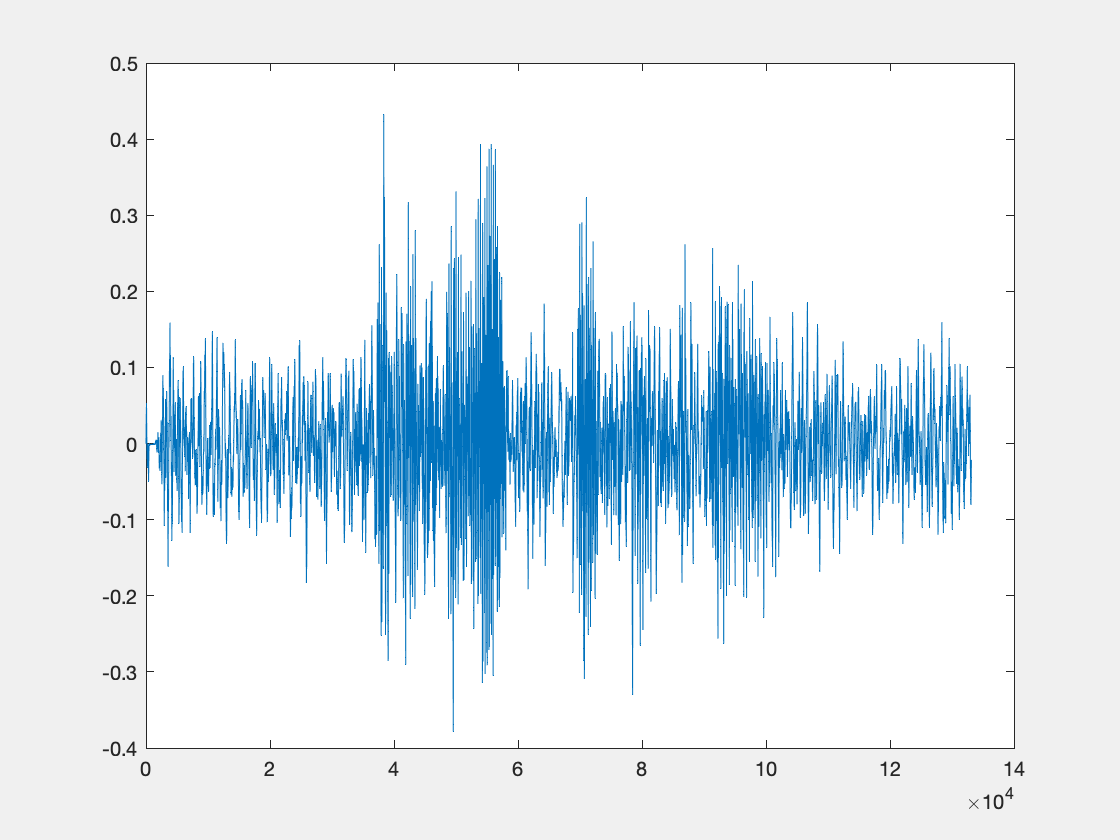

% Plot signal:
figure
plot(recSig)
set(gcf, 'Visible', 'On')


% zoom in to see extent of signal
% if the signal extends to =1 or -1 then it has clipped and
% you need to record it again

% window the signal in the time domain:
% recSig_window = recSig(1248:5.22e4);

% plot the windowed signal:

% play signal:
soundsc(recSig, 44100)


Save your time windowed signal as a wave file and upload with your lab solution.

Put your code here:

% audiowrite()

# Filtering Signals with FIR Filters

#### **Church Impulse Response (IR)**

Finite Impulse Response filters are finite sequences that correspond to the impulse response of some physical or theoretical system. Mathematically, they are described by a causal, stable sequence.

Filtering a signal with an FIR filter simulates the action of the physical or theoretical system. Let's demonstrate this. 

Consider the acoustic impulse response of a church. It could be measured using a log sine sweep or in the olden days it could be measured with a blank gun shot or the pop of a balloon.

Run the code below.

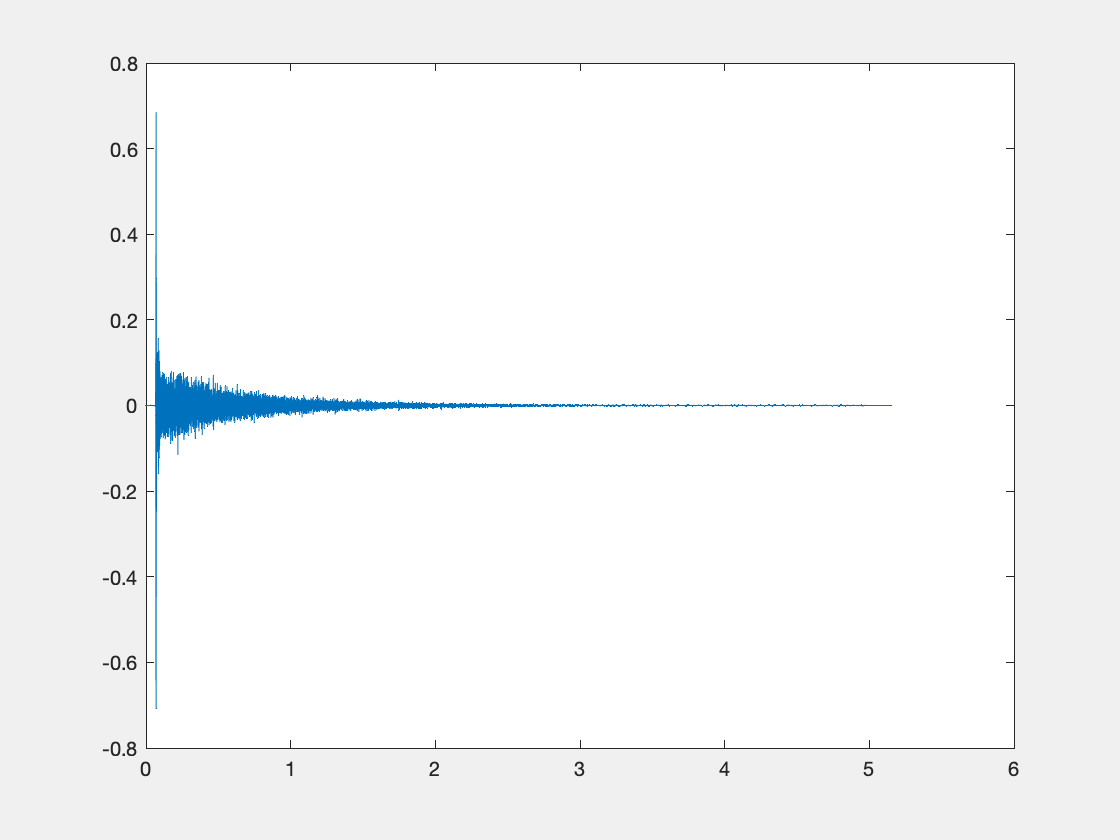

[churchIR, fsIR] = audioread('ChurchImpulseResponse-16-44p1-mono-5secs.wav');
soundsc(churchIR, fsIR)
fh = figure; set(gcf,'Visible','On')
tIR = (0:length(churchIR)-1).'/fsIR ;
plot(tIR,churchIR)

What did the impulse response sound like?

*Put your answer here:*

Let's now filter our recorded sentence with the church impulse response. This will make it seem like the speech was recorded inside the church! 

Use the Matlab function filter to filter your recorded signal with the church impulse response.

Put your code here:

sigChurch = filter(resample(churchIR, fs, fsIR), 1, recSig);

***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem A.1 to get auto-graded.***

Play the filtered audio signal. It should now sound as if it was recorded in a church!

Put your code here:

sigChurch = filter(resample(churchIR, fs, fsIR), 1, recSig);
playObj = audioplayer(sigChurch, fs);
playblocking(playObj);
playObj = audioplayer(recSig, fs);
playblocking(playObj);

% filteredSig = conv(resample(churchIR, fs, fsIR), regSig);

Since we just introduced a room impulse response, we might as well speak a little bit about room acoustics. 

Sound waves in air travel at roughly 345 m/s. Shortly after the arrival of the direct sound, a series of semi-distinct reflections arrive from various reflecting surfaces (walls, floor and ceiling). These early reflections are defined to occur within 50 to 80 milliseconds. Early reflections are not heard as separate from the direct sounds and instead reinforce the direct sound. For a rapidly varying sound such as speech the limit is closer to 50 ms while for singing and music the limit is closer to 80 ms. In other words, the concept of the early reflections is related to sound perception.

Studies have shown (e.g., Leo Beranek, 1962) that a church or concert hall is considered intimate if the delay time between the direct and first reflected sound is less than 20 ms.

Reflections that arrive after the early reflections are typically lower in amplitude and closely spaced in time. These reflections are often referred to as the late reverberation or late reflections.

The reverberation time (RT60) is generally defined as the time for the reverberant sound to decrease by 60 dB from its original level and varies with frequency.

#### Removing Early Reflections

Let's play around with these ideas. First, we will plot the early reflection period.

Plot the early reflection period of the church impulse response.

Then, zero out the early reflections in the impulse response and re-filter the recorded sound with the modified church impulse response. Play the new audio signal. You should get the impression that the direct sound is somehow lessened.

Start by defining the starting time of the church IR and the time when at the end of the early reflections (take them to last 80 ms):

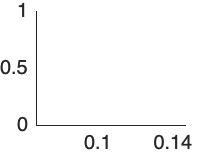

startIR = 0.067;
earlyRef = startIR +80e-3 ;
figure();
xlim([0.0671 earlyRef])


churchINoEarly = churchIR ;


Now zero-out the early reflection period in the church IR and filter the signal with the new church IR:

% zero out early reflection period in IR
churchIRNoEarly (round ( (startIR+4e-3)*fsIR) : round (earlyRef*fsIR)) = 0;
% filter signal with new church IR
sigInChurchNoEarly = filter(resample (churchIRNoEarly, fs, fsIR) , 1, recSig) ;

***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem A.2 to get auto-graded.***

Now play the signals to hear the filtered waveform:

% play signals
playObj = audioplayer(sigInChurchNoEarly, fs) ;
playblocking(playObj) ;
playObj = audioplayer(churchIR, fs)

playObj =   audioplayer with properties:

       SampleRate: 48000
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 227497
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


fs = 48000

fs = 48000

playblocking(playObj);


Is the direct sound is somehow lessened?

#### Removing Late Reverberation

Repeat the above, but now keep the early reflections and remove the late reverberation. Re-filter the recorded sound, play the new audio signal. The reverberation should now be lessened.

In the following code block, zero-out the late reflection period of the church impulse response and filter your recorded signal with this new church IR:

% zero out late reflection period in IR:
% filter signal with new church IR:
churchIRNoLate = churchIR ;
% zero out late reflection period in IR churchIRNoLate(round(earlyRef*fsIR):end)=0:
% filter signal with new church IR
sigInChurchNoLate = filter( resample (churchIRNoLate, fs, fsIR) , 1, recSig) ;


***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem A.3 to get auto-graded.***

Now play the signals to hear the filtered waveform:

% play back signals
play0bj = audioplayer (sigInChurchNoLate,fs) ;
playblocking (playObj) ;
playObj = audioplayer (sigInChurch, fs) ;
playblocking(play0bj);

Does the reverberation sound lessened?

# Truncated Ideal Low-Pass Filter

Create an ideal truncated low-pass filter based on the following formula


$$H(e^{j\,\omega}) = \left\{\begin{array}{ll}
1\cdot e^{-j\,\alpha\,\omega}\text{,} & |\omega| \lt \omega_c \\
0\text{,} & \omega_c < |\omega| \le \pi
\end{array}$$


## Compute the Analytic Solution for the impulse response below:

Show your work using latex equations below.

Put work here:


$$h\left(n\right)=\frac{1}{2\pi \;}\int_{-\omega_{c\;} }^{\omega_{c\;} } e^{-j\alpha \;\omega \;} e^{\textrm{jn}\omega \;} d\omega =\frac{1}{2\pi \;}\frac{e^{j\left(n-\alpha \;\right)\omega \;} }{j\left(n-\alpha \;\right)}=\frac{\sin \left\lbrack \omega {\;}_{c\;} \left(n-\alpha \;\right)\right\rbrack }{\pi \;\left(n-\alpha \;\right)}$$


Determine and plot the truncated impulse response 


$$h[n] \ \text{for} \ 0 \le n < N-1$$


using N = 61, $\alpha = 30$. Choose $\omega_c$ so that the cut-off frequency is 1500 Hz, using 44100 sample rate.

Put your code here


n = (0:60);
alpha = 30;
fs = 48000;
f = 1500;
wc = (f/(fs/2)) * pi;


lpFilt = (wc/pi) * sinc((wc/pi)*(n-alpha));

figure;
set(gcf,'Visible','On')
stem(n,lpFilt)     % plot the impulse response

***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem B. to get auto-graded.***

Filter your recorded speech signal with the truncated low-pass filter and play the resulting signal.

Put your code here:

regSigLPF = filter( regSig, 1, lpFilt) ;

# Truncated Ideal High-Pass Filter

Create an ideal truncated low-pass filter based on the following formula


$$H(e^{j\,\omega}) = \left\{\begin{array}{ll}
1\cdot e^{-j\,\alpha\,\omega}\text{,} & \omega_c < |\omega| \le \pi \\
0\text{,} & |\omega| \le \omega_c
\end{array}$$


## Compute the Analytic Solution for the impulse response below:

Show your work using latex equations below.

Put work here:


$$h\left\lbrack n\right\rbrack =\textrm{sinc}\left(n-\alpha \;\right)-\frac{\omega_c }{\pi \;}\textrm{sinc}\left(\frac{\omega_c }{\pi \;}\left(n-\alpha \;\right)\right)$$


Determine and plot the truncated impulse response 


$$h[n] \ \text{for} \ 0 \le n < N-1$$


using N = 61, $\alpha = 30$. Choose $\omega_c$ so that the cut-off frequency is 1500 Hz, using 44100 sample rate.

Put your code here

n = (0:60);
alpha = 30;
fs = 48000;
f = 1500;
wc = (f/(fs/2)) * pi;


hpFilt = sinc(n - alpha) - (wc/pi) * sinc((wc/pi)*(n-alpha));

figure;
set(gcf,'Visible','On')
stem(n,hpFilt)     % plot the impulse response

***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem C. to get auto-graded.***

Filter your recorded speech signal with the truncated low-pass filter and play the resulting signal.

Put your code here

regSigHPF = filter( regSig, 1, hpFilt) ;

# Create a DTFT Matlab Function

Use the example code given in class to create a MATLAB function the computes the DTFT of a finite-duration signal.  The function should have the following format

function Xfq = dtft(xn, n, omega)

% xn is finite duration signal over n

% n is the sample position vector

% omega is the frequency location vector

function X = dtft(xn, n, omega)
    % Computes the discrete-time Fourier Transform
    % X = dtft(xn,n,omega)
    %
    % X = DTFT values computed a w frequencies
    % xn = finite duration sequence over n (row vector)
    % n = sample position row vector
    % omega = frequency row vector
    
    n = n(:).';
    omega = omega(:).';
    X = xn*exp(-j*n.'*omega);
    
end

***Implement your function in MATLAB Grader Lab 2 problem D. to test it and get auto-graded. Please save a local copy to avoid losing your progress!***

# DTFT of Window Function

Use your DTFT function to compute the DTFT of the following window functions:

Rectangular $R_{M}[n] = \left\{\begin{array}{ll}
                          1\, \text{,} & 0 \le n < M \\
                          0\, \text{,} & \text{otherwise}                         
\end{array}$

Hanning $C_{M}[n] = 0.5\left[1 - \cos\left(\frac{2\,\pi\,n}{M-1}\right)\right]R_{M}[n]$

Triangular $T_{M}[n] = \left[1- \frac{|M-1-2\,n|}{M-1}\right]R_{M}[n]$

Hamming $H_{M}[n] = \left[0.54 - 0.46\cos\left(\frac{2\,\pi\,n}{M-1}\right)\right]R_{M}[n]$

Let M vary from 10, 25, 50, 101. Normalise the DTFT by dividing by its magnitude. 

Plot the normlized DTFT as a function of M for each of the window functions. Use the subplot function.

Put your code here:

% Rectangular

***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem E.1 to get auto-graded.***

% Hanning

***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem E.2 to get auto-graded.***

% Triangular

***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem E.3 to get auto-graded.***

% Hamming

***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem E.4 to get auto-graded.***

# Convolution and Deconvolution as Polynomial Multiplication and Division

Multiply the following two polynomials together using the conv_m.m Matlab function.


$$X_{1}(z) = z + 2 + 3z^{-1}$$



$$X_2(z) = 2z^{2}  + 4z + 3 + 5z^{-1}$$



$$X_3(z) = X_1(z) \cdot X_2(z)$$


Put your code here:

u= [3 2 1] ;
v= [5 3 4 2] ; //from z^-1
w_matlab=conv(u,v)

n1= [-1 : 1] ;
n2= [-1 : 2] ;
[w,nw]=conv_m(u,n1,v,n2)

***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem F.1 to get auto-graded.***

Write down the polynomial $X_3(z)$ using a latex equation below:

Put your answer here:


$$X(z) = $$


Divide the following two polynomials using the deconv_m.m Matlab function.


$$X(z) = \frac{z^{2} + z + 1 + z^{-1}+z^{-2} + z^{-3}}{z + 2 + z^{-1}}$$


Put your code here:

***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem F.2 to get auto-graded.***

Write down the polynomial $X(z)$ using a latex equation below:

Put your answer here:


$$X(z) = $$


# Second-order System

The sequence 


$$x[n] = A_{c} (r)^n \cos(\pi\,\nu_{0}\,n)\,u(n) + A_{s} (r)^n \sin(\pi \, \nu_{0}\,n)\,u(n)$$


corresponds to the following Z-Transform


$$X(z) = \frac{b_0 + b_1z^{-1}}{1+a_1z^{-1}+a_2z^{-2}} \ \text{,} \ |z| > |r|$$


where 


$$b_0 = A_c \ \text{;} \ b_1 = r\left[A_s \sin(\pi\,\nu_{0}) - A_c \cos(\pi\,\nu_{0})\right] \ \text{;} \ a_1 = -2r\,\cos(\pi\,\nu_{0}) \ \text{;} \ a_2 = r^2 \ \text{.}$$


Determine the signal parameters $A_c \, \text{,} \ A_s \, \text{,} \ r \, \text{,} \ \nu_{0}$ in terms of the rational function parameters $b_0 \, \text{,} \ b_1 \, \text{,} \ a_1 \, \text{,} \ a_2$ . Write a MATLAB function invCCPP that computes the signal parameters from the rational function parameters. 

You function shoiuld have the form:

function [Ac, As, r, v0] = invCCPP(b0, b1, a1, a2)

***Implement your function in MATLAB Grader Lab 2 problem G.1 to test it and get auto-graded. Please save a local copy to avoid losing your progress!***

Consider the Z-Transform


$$X(z) = \frac{-2 +5.65z^{-1} -2.88z^{-2}}{1 - 0.1z^{-1} + 0.09 z^{-2} +0.648 z^{-3}}$$


By clever use of the residuez function, express $X(z)$ as:


$$X(z) = \frac{( ) + ()z^{-1}}{1+()z^{-1} + ()z^{-2}} + \frac{()}{1+()z^-1}$$


Use your invCCPP function to determine the causal sequence x[n] corresponding to $X(z)$such that the sequence has no complex numbers in it.

Put your matlab code here:

***Once finished, copy and paste the above code block into MATLAB Grader Lab 2 problem G.2 to get auto-graded.***

Write down the sequence x[n] using latex below:


$$x[n] = $$
